clear; close all; clc;

% pic_num = 409;
pic_num = 561;
path = "E:/Program Files/dataset/KITTI/2011_09_26_drive_0101_sync";
original_img_path = path+'/image_2/0000000'+num2str(pic_num)+'.png';
optical_flow_path = path+'/flow/0000000'+num2str(pic_num)+'.png';
semantic_path = path + '/semantic/0000000'+num2str(pic_num)+'.png';

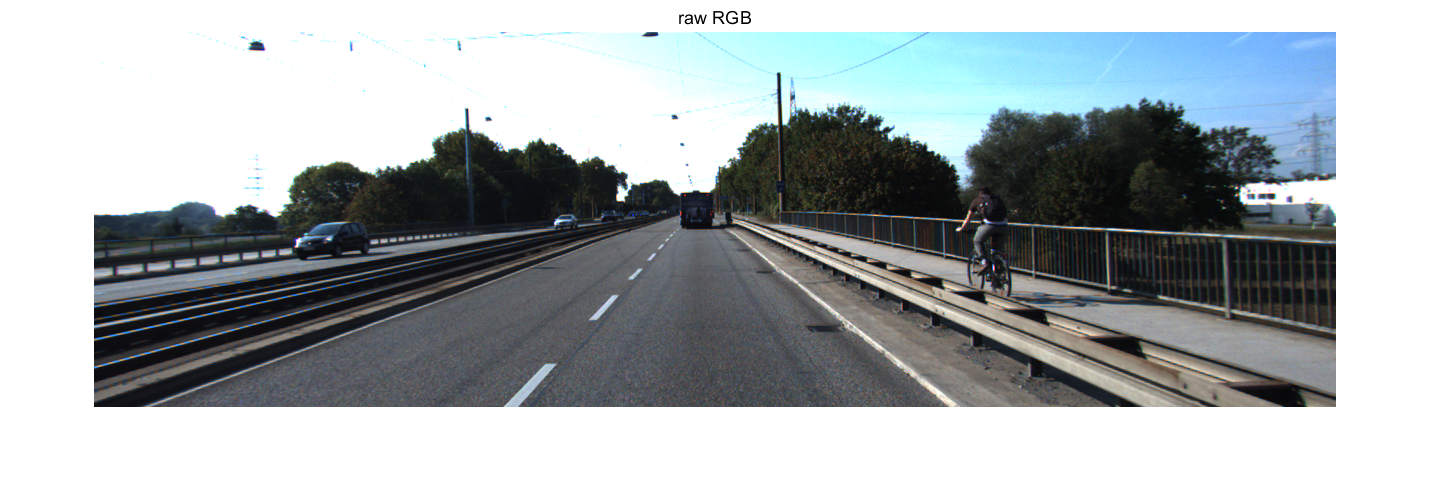


% 图1 原始RGB
rgb_img = imread(original_img_path);
fig1 = figure;
imshow(rgb_img)
title("raw RGB")
axis off

addToolbarExplorationButtons(gcf)
    

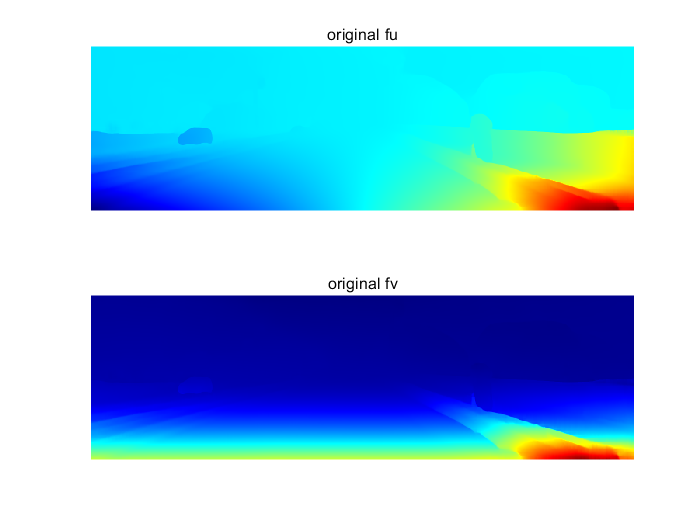


% 图2 光流图

optical_flow_img = imread(optical_flow_path);

flow_u = (double(optical_flow_img(:,:,1))-2^15)/64.0;
flow_v = (double(optical_flow_img(:,:,2))-2^15)/64.0;
flow_valid = optical_flow_img(:,:,3);
flow_u(flow_valid==0) = nan;
flow_v(flow_valid==0) = nan;

fig2 = figure;
subplot(2,1,1); imshow(flow_u, [], 'Colormap', jet(4096));title("original fu")
subplot(2,1,2); imshow(flow_v, [], 'Colormap', jet(4096));title("original fv")


addToolbarExplorationButtons(gcf)
    

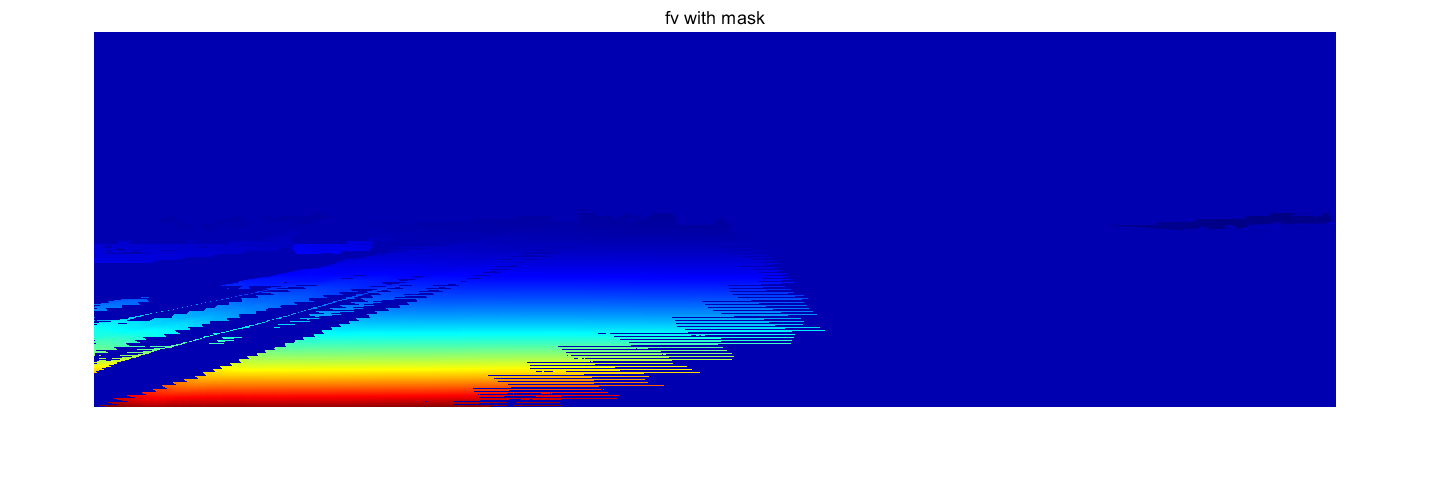


% 获取路面的mask 
semantic_img = imread(semantic_path);
%imshow(semantic_img)
mask=zeros(size(semantic_img,1),size(semantic_img,2),"double");
for i = 1 : size(semantic_img,1)
    for j = 1 : size(semantic_img,2)
        if semantic_img(i,j,1)==255 ...
            && semantic_img(i,j,2)==0 ...
            && semantic_img(i,j,3)==0
  
            mask(i,j)=1;
        end
    end
end


%图3 光流fv图带掩码 

flow_u = flow_u .* mask;
flow_v = flow_v .* mask;

figure;
imshow(flow_v, [], 'Colormap', jet(4096));title("original fu")
title("fv with mask")
axis('off')


% 图4 v-fv曲线图

[v_max, u_max, ~] = size(flow_u);
image_h = v_max;
image_w = u_max;

u0 = 696.02;
v0 = 224.18;

for i = 1: v_max
    for j = 1: range(u_max)
        if flow_v(i, j) + i > v_max
            flow_v(i, j) = 0 ;
        end
    end
end

 
v_fv_map = zeros(v_max, round(max(flow_v,[],'all')));
for i = 1:v_max
    for j = 1:u_max
        fv_id= round(flow_v(i, j));
        if fv_id >0 
             v_fv_map(i, fv_id) = v_fv_map(i, fv_id)+1;
        end
       
    end
end

fig4 = figure;
imshow(v_fv_map, [], 'Colormap', jet(4096));
title("v-fv-map")
axis off
addToolbarExplorationButtons(gcf)


% v-fv公式计算图 

% fv = Zd(v1-v0)/(hf/(v1-v0)-Zd)
% Y = Zd*X^2 / (hf - Zd*X)
% f = fx = fy = image_w / 2.0
% h = 2.4


v1 = 1:0.1:v_max;
v1 = v1(v1 - v0 > 0);

%选取中间非零点
v_head = v0;
v_tail = v_max;
for i = round(v0) + 1 : v_max
    [~,max_index]=max(v_fv_map(i, :));
    if max_index ~= 1
        v_head = i;
        break
    end
end

for i = v_head : v_max
    [~,max_index]=max(v_fv_map(i, :));
    if max_index == 1
        v_tail = i + 1;
        break
    end
end



% 曲线拟合
fo = fitoptions('Method','NonlinearLeastSquares',...
               'Lower',[0,0],...
               'Upper',[2000,300],...
               'StartPoint',[700 173]);
f=fittype('(x - v0) ^ 2 / (a - (x - v0))','independent','x', ...
            'coefficients',{'a','v0'},'options',fo);
x=v_head:v_tail;  x=x';
[~,max_index]=max(v_fv_map,[],2);
y=max_index(v_head:v_tail);

cfun=fit(x,y,f)

cfun =      General model:
     cfun(x) = (x - v0) ^ 2 / (a - (x - v0))
     Coefficients (with 95% confidence bounds):
       a =       704.1  (698.5, 709.8)
       v0 =       179.4  (178.7, 180.1)

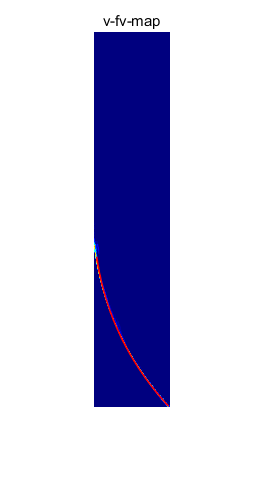

hold on
Y=cfun(x);
% v0=172.47854488639362;
% a=685.6171777531607; 
% Y=(x - v0.*ones(size(x))) .^ 2 / (a.*ones(size(x)) - (x - v0.*ones(size(x))));
plot(Y, x, 'r','LineWidth',1)

% fprintf("popt[0]=%f,popt[1]=%f", cfun, popt[1])

%     opts = statset('nlinfit');
%     opts.RobustWgtFun = 'bisquare';
%     
%     modelfun_simplified = @(b,v)(...
%         (x - b(1)) ^ 2 / (b(0) - (x - b(1))));
%     
%     %     b0 = [60;50;32;50];
%     b = nlinfit(V_tmp,fv_tmp,modelfun_simplified,b0,opts);
%     %     fv = V.*((b(3)-b(1))+(b(4)-b(2))*V)./((b(4)-b(2))*V-b(3));
%     b0 = b;
%     v  = v;
%     fv = (v.*((b(3)-b(1))+(b(4)-b(2))*v))./((b(4)-b(2))*v-b(3));
